clear;
clc;
% Given
Pe = 100;
gamma = 1.4;
cp = 1006;

% Entrance
P1 = 100;
T1 = 293;

% Compressor Exit
P2 = [100:1:5000]%1500 %variable

P2 =    100   101   102   103   104   105   106   107   108   109   110   111   112   113   114   115   116   117   118   119   120   121   122   123   124   125   126   127   128   129   130   131   132   133   134   135   136   137   138   139   140   141   142   143   144   145   146   147   148   149


T2 = T1.*(P2./P1).^((gamma-1)/gamma);

% Cumbustion chamber exit
P3 = P2;
T3 = 1600%1313;

T3 = 1600

% Turbine Exit
%T2-T1=T3-T4
T4 = T3 + T1 - T2;
P4 = P3.*(T4./T3).^(gamma/(gamma-1));

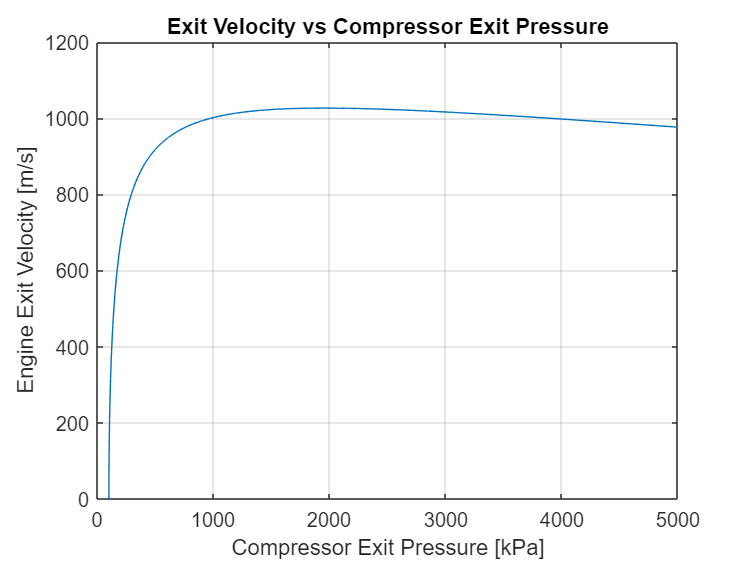

% Nozzle Exit
Te = T4.*(Pe./P4).^((gamma-1)/gamma);

ue = sqrt(2*cp*(T4-Te));
plot(P2, ue)
title("Exit Velocity vs Compressor Exit Pressure")
xlabel("Compressor Exit Pressure [kPa]")
ylabel("Engine Exit Velocity [m/s]")
grid on

max(ue)

ans = 1.0264e+03

i = find(ue==max(ue));
%P2(i)
r = P2(i)/P1

r = 19.5100


%Thrust
%mdot = 64.14
%R = mdot*(ue)
%mdot = R/ue(i)

% %Afterburner
% R2 = 70000
% 
% ue2 = R2/mdot
% 
% %T5 - Te2 = T4 - Te
% P5 = P4
% T5 = ue2^2/(2*cp*(1-.6292))